1.multicylinder

Create geometry formed by several cylindrical cells

[`gm = multicylinder(R,H)`](https://ww2.mathworks.cn/help/pde/ug/multicylinder.html#d120e59087)

[`gm = multicylinder(R,H,Name,Value)`](https://ww2.mathworks.cn/help/pde/ug/multicylinder.html#d120e59115)

[`gm`](https://ww2.mathworks.cn/help/pde/ug/multicylinder.html#bvj_iq2-gm) `= multicylinder(`[`R`](https://ww2.mathworks.cn/help/pde/ug/multicylinder.html#bvj_iq2-R)`,`[`H`](https://ww2.mathworks.cn/help/pde/ug/multicylinder.html#bvj_iq2-H)`)` creates a geometry by combining several cylindrical cells.

When creating each cylinder, `multicylinder` uses the following coordinate system.

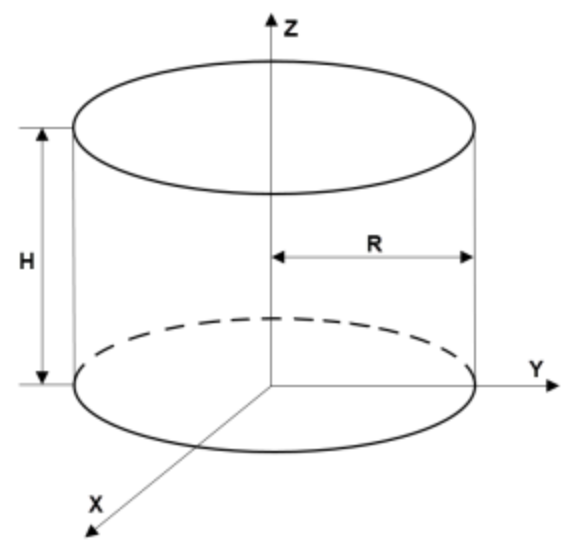

1.1 同心圆柱

gm = multicylinder([5 10 15],2)

gm =   DiscreteGeometry - 属性:

       NumCells: 3
       NumFaces: 9
       NumEdges: 6
    NumVertices: 6


model = createpde

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: []
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


model.Geometry = gm

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: [1×1 DiscreteGeometry]
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


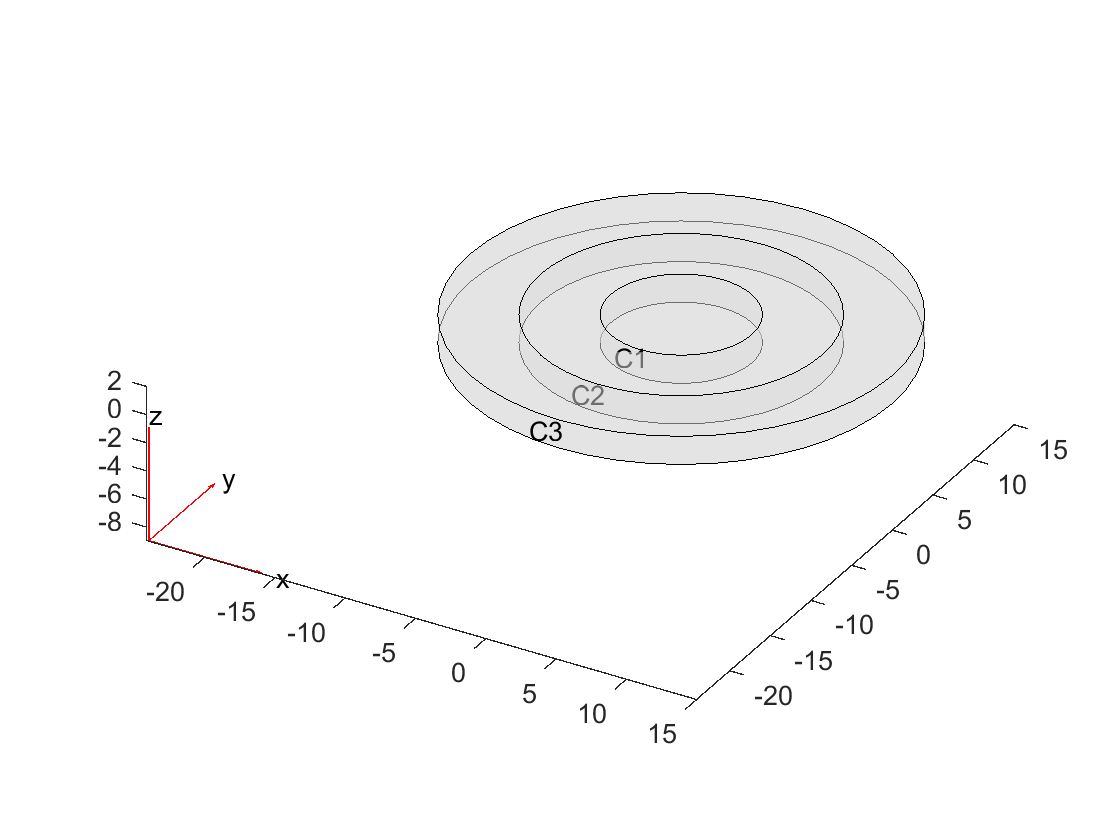

pdegplot(model,'CellLabels','on','FaceAlpha',0.5)

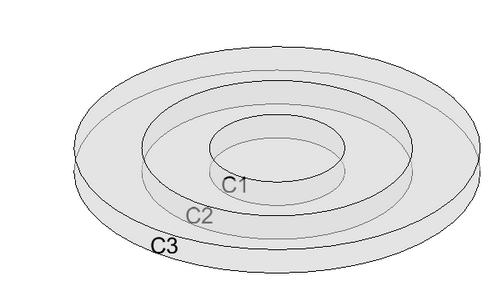

1.2 堆叠圆柱

Create the geometry by using the `multicylinder` function with the `ZOffset` argument. The resulting geometry consists of four cells stacked on top of each other.（用法和多体长方体一样。）

gm = multicylinder(10,[1 2 3 4],'ZOffset',[0 1 3 6])

gm =   DiscreteGeometry - 属性:

       NumCells: 4
       NumFaces: 9
       NumEdges: 5
    NumVertices: 5


model = createpde

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: []
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


model.Geometry = gm

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: [1×1 DiscreteGeometry]
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


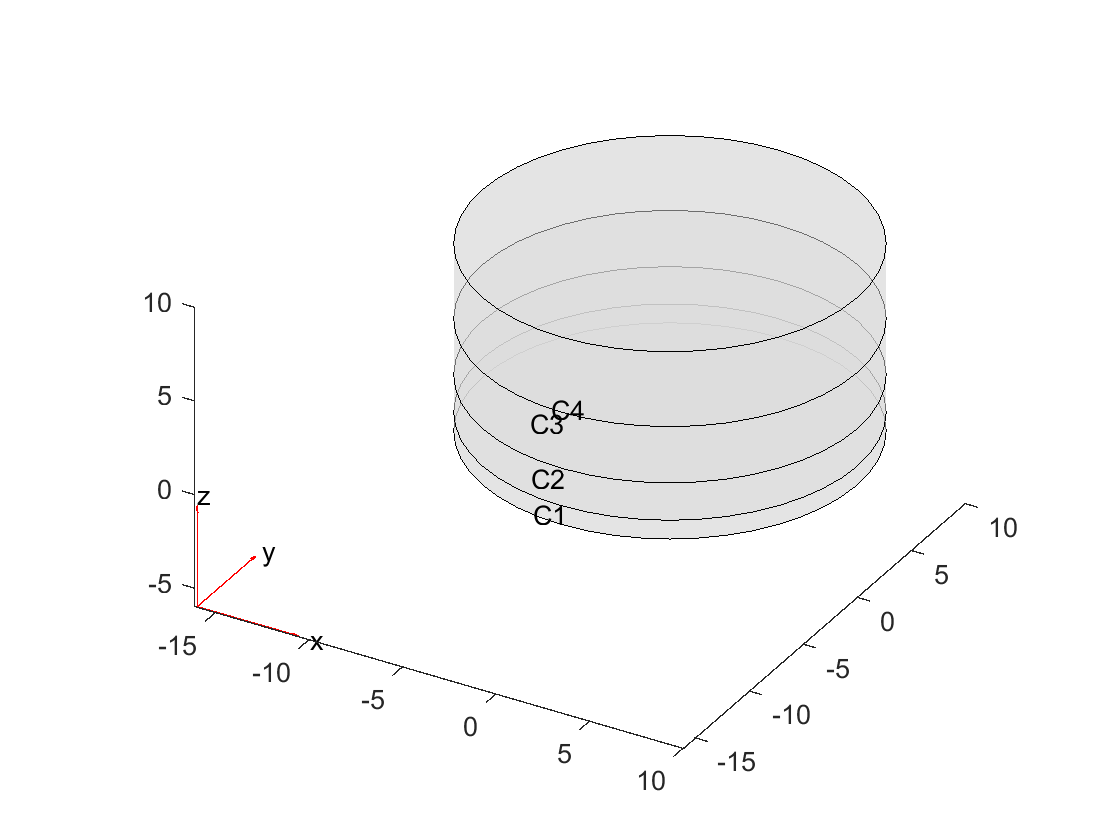

pdegplot(model,'CellLabels','on','FaceAlpha',0.5)

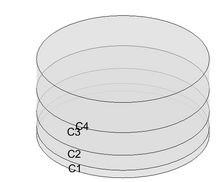

1.3 空洞圆柱体

gm = multicylinder([9 10],10,'Void',[true,false])

gm =   DiscreteGeometry - 属性:

       NumCells: 1
       NumFaces: 4
       NumEdges: 4
    NumVertices: 4


model = createpde

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: []
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


model.Geometry = gm

model =   PDEModel - 属性:

           PDESystemSize: 1
         IsTimeDependent: 0
                Geometry: [1×1 DiscreteGeometry]
    EquationCoefficients: []
      BoundaryConditions: []
       InitialConditions: []
                    Mesh: []
           SolverOptions: [1×1 PDESolverOptions]


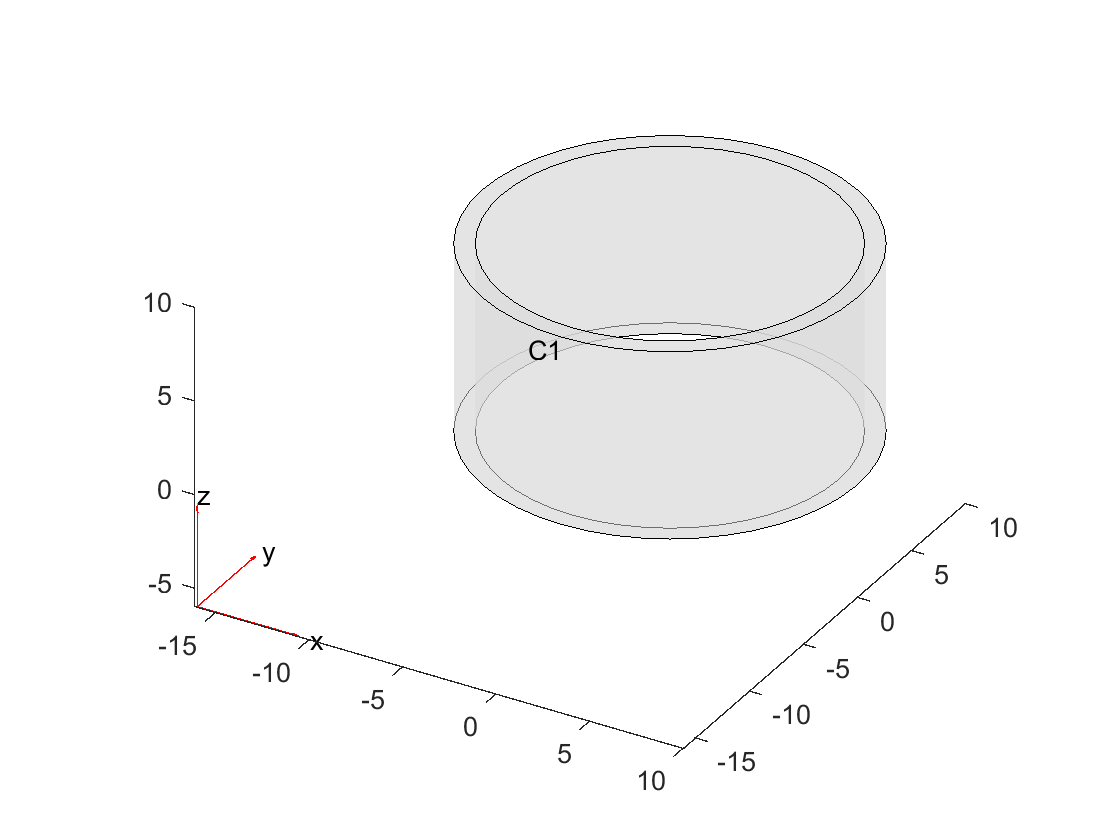

pdegplot(model,'CellLabels','on','FaceAlpha',0.5)